% 直流电动机
Ued = 5;
Ied = 4;
ned = 5;
Ce = 0.556;
lambda = 1.2;

Ud = Ued;

% PWM逆变器
Ks = 1;
Ts = 0.01;
R = 0.6;
Tl = 0.167;
Tm = 0.282;

alpha = 1;
beta = 1;

% I型系统
% Ki = 5;
% tau_i = 0.167;

% II型系统
% Ki = 6;
% tau_i = 0.05;
% 
% Kn = 7.84;
% tau_n = 0.1;

% Ki = 1;
% tau_i = 0.47;
% 
% Kn = 3.6;
% tau_n = 0.36;

ned = 2;
mdl = 'paper';
in = Simulink.SimulationInput(mdl); 
in = in.setVariable('Kn',solution.Kn,'Workspace',mdl);
in = in.setVariable('tau_n',solution.tau_n,'Workspace',mdl);
in = in.setVariable('Ki',solution.Ki,'Workspace',mdl);
in = in.setVariable('tau_i',solution.tau_i,'Workspace',mdl);
out = sim(in);

out.plot
stepinfo(out.yout.get('n').Values.Data(1:321, :), out.yout.get('n').Values.Time(1:321, :))

ans = 0.1573

ans =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0004
    0.0018
    0.0050
    0.0097


ans = 包含以下字段的 struct :
         RiseTime: 0.0702
    TransientTime: 0.2551
     SettlingTime: 0.2551
      SettlingMin: 1.9282
      SettlingMax: 2.3147
        Overshoot: 15.7273
       Undershoot: 6.6730e-70
             Peak: 2.3147
         PeakTime: 0.1200


% Create optimization variables
Ki = optimvar("Ki","LowerBound",0,"UpperBound",20);
Kn = optimvar("Kn","LowerBound",0,"UpperBound",20);
tau_i = optimvar("tau_i","LowerBound",0,"UpperBound",20);
tau_n = optimvar("tau_n","LowerBound",0,"UpperBound",20);

% Set initial starting point for the solver
initialPoint.Ki = ones(size(Ki));
initialPoint.Kn = repmat(3.6,size(Kn));
initialPoint.tau_i = repmat(0.47,size(tau_i));
initialPoint.tau_n = repmat(0.36,size(tau_n));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@cost_func,Ki,Kn,tau_i,tau_n);

% 设置非默认求解器选项
options = optimoptions("ga","Display","iter","PlotFcn",["gaplotdistance",...
    "gaplotgenealogy","gaplotselection","gaplotscorediversity",...
    "gaplotscores","gaplotstopping","gaplotmaxconstr","gaplotbestf",...
    "gaplotbestindiv","gaplotexpectation","gaplotrange"]);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       Ki, Kn, tau_i, tau_n

	minimize :
       cost_func(Ki, Kn, tau_i, tau_n)


	variable bounds:
       0 <= Ki <= 20

       0 <= Kn <= 20

       0 <= tau_i <= 20

       0 <= tau_n <= 20



Solving problem using ga.

Single objective optimization:
4 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           0.407           6.124        0
    2              147           0.407           3.001        1
    3              194          0.3644           2.869        0
    4              241          0.3618           2.048        0
    5              288          0.3068           1.961        0
    6              335          0.3068           1.887        1
    7              382          0.2949           1.865        0
    8              429          0.2949          0.3869        1
    9              476          0.2696          0.3573        0
   10              523          0.2577          0

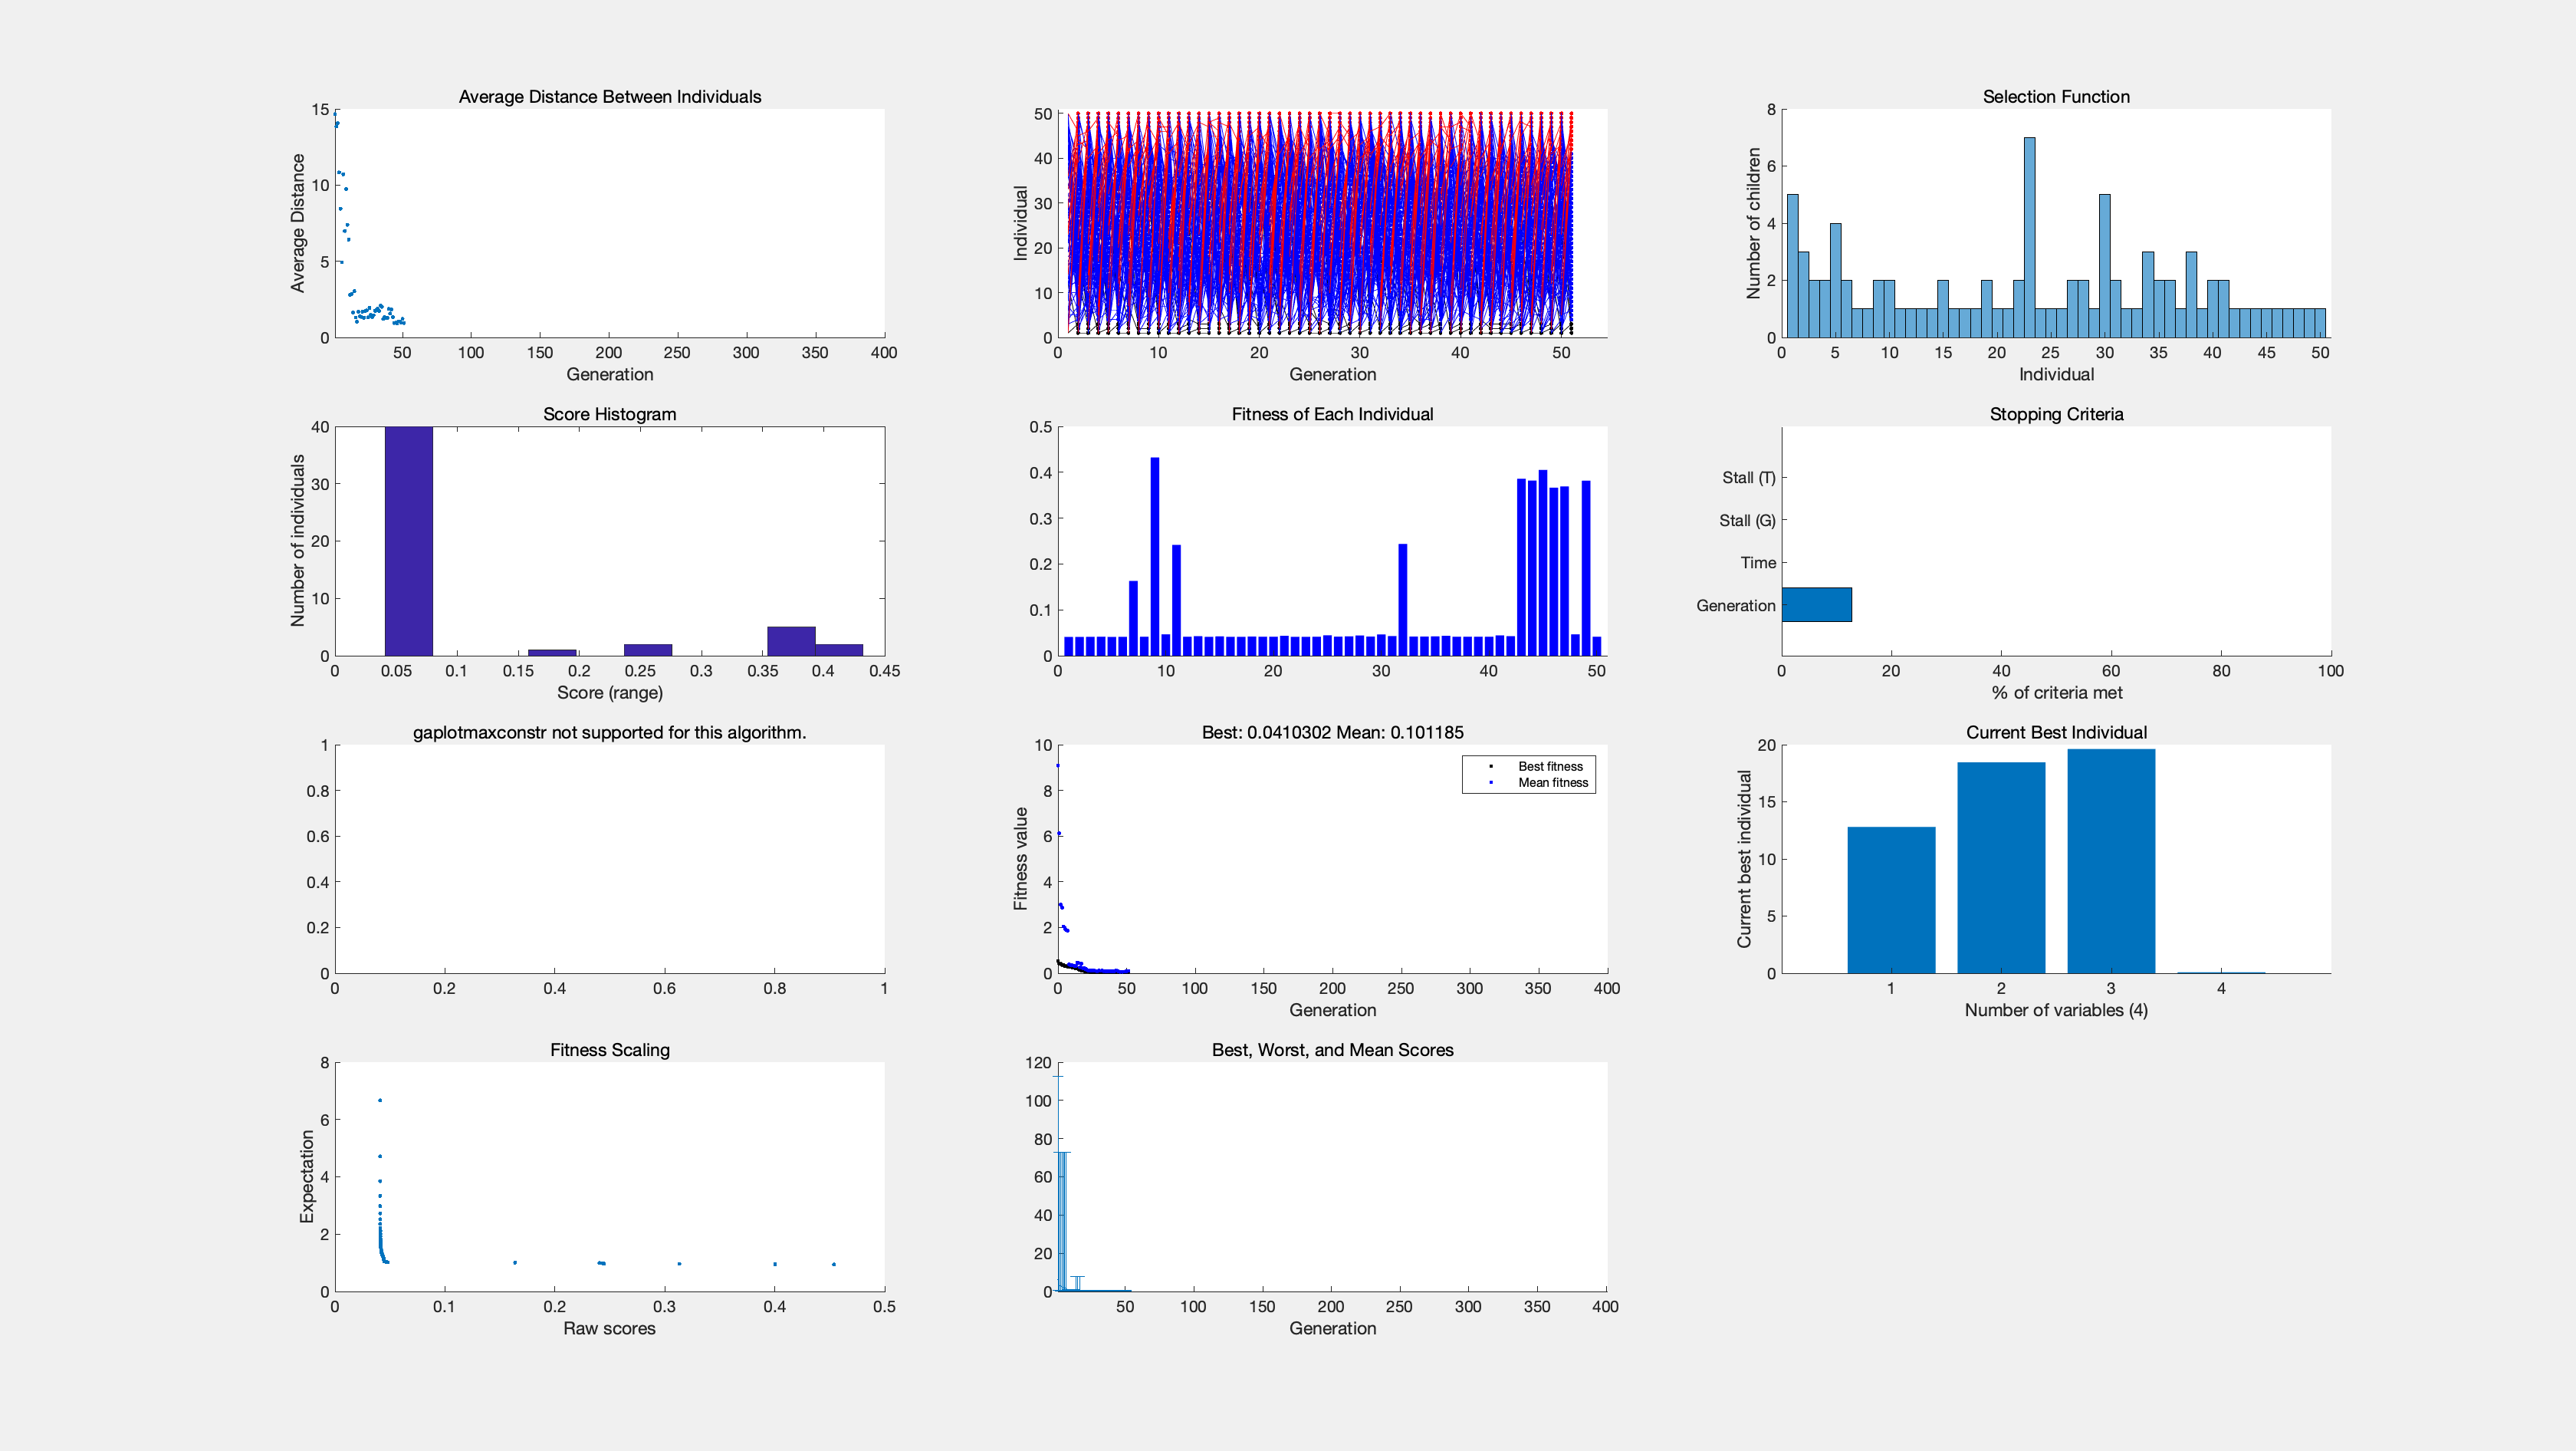


% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","ga","Options",options);


% Display results
solution

solution = 包含以下字段的 struct :
       Ki: 13.9242
       Kn: 18.4605
    tau_i: 19.3757
    tau_n: 0.0859


reasonSolverStopped

reasonSolverStopped =     OutputFcnStop


objectiveValue

objectiveValue = 0.0410


% 清除变量
clearvars Ki Kn tau_i tau_n initialPoint options reasonSolverStopped...
    objectiveValue